data_summary_csv = '/Users/pingchuanma/Desktop/ChenLab_Data/RvR/New_RvR_analysis/Pingchuan_RvR_Raw_files_delay_corrected/Scatter Plot (Raw)_grouped_PeterRevised_20230723.csv';
summary_path = '/Users/pingchuanma/Desktop/ChenLab_Data/RvR/New_RvR_analysis/Pingchuan_RvR_Raw_files_delay_corrected/'

summary_path = '/Users/pingchuanma/Desktop/ChenLab_Data/RvR/New_RvR_analysis/Pingchuan_RvR_Raw_files_delay_corrected/'

cd(summary_path)

data_summary = readtable(data_summary_csv, 'NumHeaderLines', 1)

data_summary = 459×7 table
              Var1               Var2    Var3    Var4       Var5        Var6      Var7 
    _________________________    ____    ____    ____    __________    ______    ______

    {'20220325_1610_RvR_001'}    1610     1       0      3.7357e+05    2.4876    4.1805
    {'20220325_1610_RvR_001'}    1610     1       0       3.771e+05    2.4904    4.1823
    {'20220325_1610_RvR_001'}    1610     1       0      3.7982e+05    2.4931    4.1842
    {'20220325_1610_RvR_001'}    1610     1       0      3.8305e+05    2.5008     4.187
    {'20220325_1610_RvR_001'}    1610     1       0      3.8394e+05     2.501    4.1899
    {'20220325_1610_RvR_001'}    1610     1       0      3.8512e+05    2.5061    4.1937
    {'20220325_1610_RvR_001'} 

Mouse_ID = table2array(data_summary(:,2))

Mouse_ID =         1610
        1610
        1610
        1610
        1610
        1610
        1610
        1610
        1610
        1610


Laser = table2array(data_summary(:,3))

Laser =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


Speed = table2array(data_summary(:,4))

Speed =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


intensity = table2array(data_summary(:,5))/100000;
lft = table2array(data_summary(:,7))

lft =     4.1805
    4.1823
    4.1842
    4.1870
    4.1899
    4.1937
    4.1916
    4.1904
    4.1960
    4.1934


Mouse_ID_categorical = categorical(Mouse_ID)

Mouse_ID_categorical = 459×1 categorical array
     1610 
     1610 
     1610 
     1610 
     1610 
     1610 
     1610 
     1610 
     1610 
     1610 
     1610 
     1610 
     1610 
     1610 
     1610 
     1610 
     1610 
     1610 
     1610 
     1610 
     1610 
     1610 
     1610 
     1610 
     1610 
     1610 
     1610 
     1610 
     1610 
     1610 


Laser_categorical = categorical(Laser);
States =  zeros(length(Speed),1);
Running_index = [];

for i = 1:length(Speed)
    if Speed(i,1) > 0
        States(i) = 1;
        Running_index = [Running_index i];
    end
end

States_categorical = categorical(States);

mouse_all = categories(Mouse_ID_categorical)

mouse_all = 6×1 cell array
    {'1610'}
    {'1611'}
    {'1612'}
    {'1626'}
    {'1629'}
    {'1630'}


laser_all = categories(Laser_categorical)

laser_all = 3×1 cell array
    {'1'}
    {'2'}
    {'3'}


States_all = categories(States_categorical)

States_all = 2×1 cell array
    {'0'}
    {'1'}


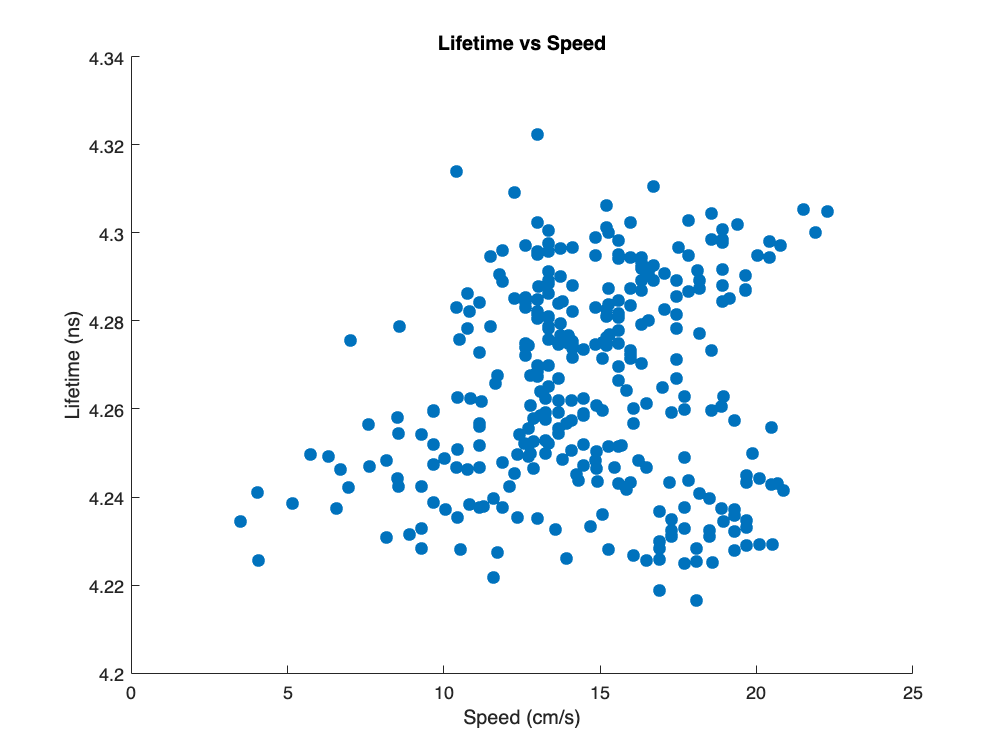

Speed_running = Speed(Running_index);
lft_running = lft(Running_index);

figure
scatter(Speed(Running_index), lft(Running_index), 50, 'filled')
xlabel('Speed (cm/s)')
ylabel('Lifetime (ns)')
title('Lifetime vs Speed')

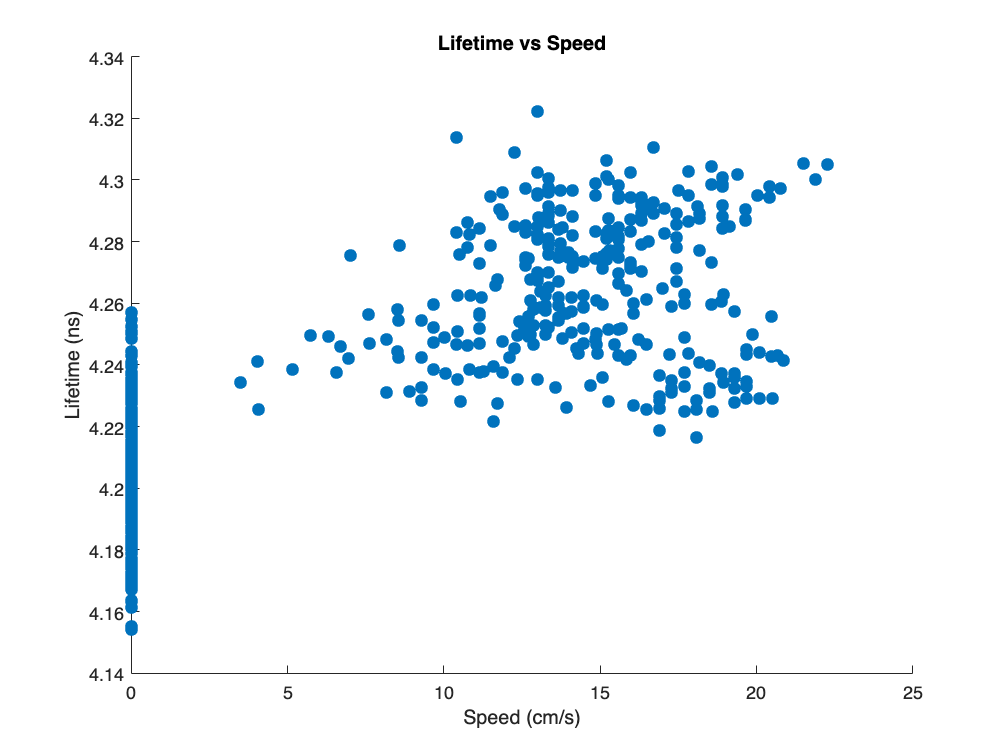

figure
scatter(Speed, lft, 50, 'filled')
xlabel('Speed (cm/s)')
ylabel('Lifetime (ns)')
title('Lifetime vs Speed')

[rho, p] = corr(Speed(Running_index), lft(Running_index))

d_intensity_resting = intensity(find(States == 0));
d_intensity_running = intensity(find(States == 1));

d_lft_resting = lft(find(States == 0));
d_lft_running = lft(find(States == 1));


lft_tbl = table(States_categorical, Mouse_ID_categorical, Laser_categorical, lft)

lft_tbl = 459×4 table
    States_categorical    Mouse_ID_categorical    Laser_categorical     lft  
    __________________    ____________________    _________________    ______

            0                     1610                    1            4.1805
            0                     1610                    1            4.1823
            0                     1610                    1            4.1842
            0                     1610                    1             4.187
            0                     1610                    1            4.1899
            0                     1610                    1            4.1937
            0                     1610                    1            4.1916
            0                     1610                    1            4.1904
            0                     1610                    1  

mdl1=stepwiseglm(lft_tbl,'constant', 'Upper', 'interactions','Criterion','adjrsquared')

1. Adding States_categorical, AdjRsquared = 0.73181
2. Adding Laser_categorical, AdjRsquared = 0.89796
3. Adding Mouse_ID_categorical, AdjRsquared = 0.91514
4. Adding Mouse_ID_categorical:Laser_categorical, AdjRsquared = 0.95112
5. Adding States_categorical:Mouse_ID_categorical, AdjRsquared = 0.95673


mdl1 = Generalized linear regression model:
    lft ~ 1 + States_categorical*Mouse_ID_categorical + Mouse_ID_categorical*Laser_categorical
    Distribution = Normal

Estimated Coefficients:
                                                       Estimate        SE         tStat        pValue  
                                                      __________    _________    ________    __________

    (Intercept)                                           4.1943    0.0017405      2409.7             0
    States_categorical_1                                0.060477    0.0022739      26.597    3.0447e-93
    Mouse_ID_categorical_1611                          0.0010261    0.0028479     0.36029        0.7188
    Mouse_ID_categorical_1612                         -0.0015986    0.0023096    -0.6

contributions_lifetime = zeros(1,3);
contributions_lifetime(1) = mdl1.Steps.History.AdjRsquared(2);
contributions_lifetime(2) = mdl1.Steps.History.AdjRsquared(3) - mdl1.Steps.History.AdjRsquared(2);
contributions_lifetime(3) = mdl1.Steps.History.AdjRsquared(4) - mdl1.Steps.History.AdjRsquared(3)

contributions_lifetime =     0.7318    0.1661    0.0172


contributions_lifetime = contributions_lifetime*100;

intensity_tbl = table(States_categorical, Mouse_ID_categorical, Laser_categorical, intensity)

intensity_tbl = 459×4 table
    States_categorical    Mouse_ID_categorical    Laser_categorical    intensity
    __________________    ____________________    _________________    _________

            0                     1610                    1             3.7357  
            0                     1610                    1              3.771  
            0                     1610                    1             3.7982  
            0                     1610                    1             3.8305  
            0                     1610                    1             3.8394  
            0                     1610                    1             3.8512  
            0                     1610                    1             3.8393  
            0                     1610                    1             3.8181  
            0            

mdl2=stepwiseglm(intensity_tbl,'constant', 'Upper','Linear','Criterion','adjrsquared')

1. Adding Mouse_ID_categorical, AdjRsquared = 0.58992
2. Adding Laser_categorical, AdjRsquared = 0.88327
3. Adding States_categorical, AdjRsquared = 0.91131


mdl2 = Generalized linear regression model:
    intensity ~ 1 + States_categorical + Mouse_ID_categorical + Laser_categorical
    Distribution = Normal

Estimated Coefficients:
                                 Estimate       SE        tStat       pValue   
                                 ________    ________    _______    ___________

    (Intercept)                   4.1345     0.055304     74.761    7.0006e-256
    States_categorical_1         0.51681     0.043132     11.982     6.6352e-29
    Mouse_ID_categorical_1611    -2.3305     0.095705    -24.351     3.6178e-84
    Mouse_ID_categorical_1612     1.2927     0.074336      17.39     3.4815e-52
    Mouse_ID_categorical_1626    -1.4948     0.081598    -18.319     2.0518e-56
    Mouse_ID_categorical_1629

contributions_lifetime = zeros(1,3);
contributions_lifetime(1) = mdl2.Steps.History.AdjRsquared(2);
contributions_lifetime(2) = mdl2.Steps.History.AdjRsquared(3) - mdl2.Steps.History.AdjRsquared(2);
contributions_lifetime(3) = mdl2.Steps.History.AdjRsquared(4) - mdl2.Steps.History.AdjRsquared(3)

contributions_lifetime =     0.5899    0.2933    0.0280


contributions_lifetime = contributions_lifetime*100;

lft_running=lft(find(States==1));
lft_resting=lft(find(States==0));

intensity_running=intensity(find(States==1));
intensity_resting=intensity(find(States==0));

intensity_collection=[];
lft_collection=[];
mouseID_collection=[];
laser_collection=[];
states_collection=[];

for i=1:6
    mouse=mouse_all(i)
    

    lft_mouse=lft(find(Mouse_ID_categorical == mouse));
    intensity_mouse=intensity(find(Mouse_ID_categorical == mouse));
    speed_mouse=Speed(find(Mouse_ID_categorical == mouse));
    laser_mouse=Laser(find(Mouse_ID_categorical == mouse));
    states_mouse=States(find(Mouse_ID_categorical == mouse));

    eval(['lft_',convertStringsToChars(cell2mat(mouse)),'=lft_mouse;'])
    eval(['intensity_',convertStringsToChars(cell2mat(mouse)),'=intensity_mouse;'])
    eval(['speed_',convertStringsToChars(cell2mat(mouse)),'=speed_mouse;'])
    eval(['laser_',convertStringsToChars(cell2mat(mouse)),'=laser_mouse;'])
    eval(['states_',convertStringsToChars(cell2mat(mouse)),'=states_mouse;'])

    for j=1:3

        lft_mouse_laser=lft_mouse(find(laser_mouse==j));
        intensity_mouse_laser=intensity_mouse(find(laser_mouse==j));
        speed_mouse_laser=speed_mouse(find(laser_mouse==j));
        states_mouse_laser=states_mouse(find(laser_mouse==j));
        lft_mouse_laser_running=lft_mouse_laser(find(states_mouse_laser==1));
        lft_mouse_laser_resting=lft_mouse_laser(find(states_mouse_laser==0));
        intensity_mouse_laser_running=intensity_mouse_laser(find(states_mouse_laser==1));

        mouseID_collection=[mouseID_collection;str2num(cell2mat(mouse))];
        laser_collection=[laser_collection;j];
        states_collection=[states_collection;[1]];
        if isempty(intensity_mouse_laser_running)
            intensity_collection=[intensity_collection;[NaN]];
        else
            intensity_collection=[intensity_collection;mean(intensity_mouse_laser_running)];
        end

        if isempty(lft_mouse_laser_running)
            lft_collection=[lft_collection;[NaN]];
        else
            lft_collection=[lft_collection;mean(lft_mouse_laser_running)];
        end

        intensity_mouse_laser_resting=intensity_mouse_laser(find(states_mouse_laser==0));

        mouseID_collection=[mouseID_collection;str2num(cell2mat(mouse))];
        laser_collection=[laser_collection;[j]];
        states_collection=[states_collection;[0]];
        if isempty(intensity_mouse_laser_resting)
            intensity_collection=[intensity_collection;[NaN]];
        else
            intensity_collection=[intensity_collection;mean(intensity_mouse_laser_resting)];
        end

        if isempty(lft_mouse_laser_resting)
            lft_collection=[lft_collection;[NaN]];
        else
            lft_collection=[lft_collection;mean(lft_mouse_laser_resting)];
        end

      
        

        eval(['lft_',convertStringsToChars(cell2mat(mouse)),'_',num2str(j),'=lft_mouse_laser;'])
        eval(['intensity_',convertStringsToChars(cell2mat(mouse)),'_',num2str(j),'=intensity_mouse_laser;'])
        eval(['speed_',convertStringsToChars(cell2mat(mouse)),'_',num2str(j),'=speed_mouse_laser;'])
        eval(['states_',convertStringsToChars(cell2mat(mouse)),'_',num2str(j),'=states_mouse_laser;'])

        lft_mouse_laser_running = [lft_mouse_laser_running;NaN(100-length(lft_mouse_laser_running), 1)];
        lft_mouse_laser_resting = [lft_mouse_laser_resting;NaN(100-length(lft_mouse_laser_resting), 1)];
        intensity_mouse_laser_running = [intensity_mouse_laser_running;NaN(100-length(intensity_mouse_laser_running), 1)];
        intensity_mouse_laser_resting = [intensity_mouse_laser_resting;NaN(100-length(intensity_mouse_laser_resting), 1)];
        eval(['lft_',convertStringsToChars(cell2mat(mouse)),'_',num2str(j),'_running','=lft_mouse_laser_running;'])
        eval(['lft_',convertStringsToChars(cell2mat(mouse)),'_',num2str(j),'_resting','=lft_mouse_laser_resting;'])
        eval(['intensity_',convertStringsToChars(cell2mat(mouse)),'_',num2str(j),'_running','=intensity_mouse_laser_running;'])
        eval(['intensity_',convertStringsToChars(cell2mat(mouse)),'_',num2str(j),'_resting','=intensity_mouse_laser_resting;'])
    end

end

mouse = 1×1 cell array
    {'1610'}


mouse = 1×1 cell array
    {'1611'}


mouse = 1×1 cell array
    {'1612'}


mouse = 1×1 cell array
    {'1626'}


mouse = 1×1 cell array
    {'1629'}


mouse = 1×1 cell array
    {'1630'}



FYI=[mouseID_collection laser_collection states_collection intensity_collection lft_collection];

for i = 1:6
    mouse=convertStringsToChars(cell2mat(mouse_all(i)));
    mouse_intensity_AllLaser = NaN(3,100);
    mouse_lft_AllLaser = NaN(3,100);

    for j = 1:3

        eval(['intensity_this_mousepower_resting = intensity_', mouse, '_', num2str(j),'_resting;'])
        eval(['intensity_this_mousepower_running = intensity_', mouse, '_', num2str(j),'_running;'])
        eval(['lft_this_mousepower_resting = lft_', mouse, '_', num2str(j),'_resting;'])
        eval(['lft_this_mousepower_running = lft_', mouse, '_', num2str(j),'_running;'])

        if isempty(intensity_this_mousepower_resting) == 0
            mouse_intensity_AllLaser(j,1:length(intensity_this_mousepower_resting)) = intensity_this_mousepower_resting;
            mouse_intensity_AllLaser(j,51:50+length(intensity_this_mousepower_running)) = intensity_this_mousepower_running;
            mouse_lft_AllLaser(j,1:length(lft_this_mousepower_resting)) = lft_this_mousepower_resting;
            mouse_lft_AllLaser(j,51:50+length(lft_this_mousepower_running)) = lft_this_mousepower_running;
        end
    end

    eval(['a_', mouse, '_intensity_AllLaser = mouse_intensity_AllLaser;'])
    eval(['a_', mouse, '_lft_AllLaser = mouse_lft_AllLaser;'])
end

for i = 1:3
    
    power = ['power',num2str(i)];
    laser_intensity_AllMice = NaN(6,100);
    laser_lft_AllMice = NaN(6,100);

    for j = 1:6
        mouse=convertStringsToChars(cell2mat(mouse_all(j)));

        eval(['intensity_this_mousepower_resting = intensity_', mouse, '_', num2str(i),'_resting;'])
        eval(['intensity_this_mousepower_running = intensity_', mouse, '_', num2str(i),'_running;'])
        eval(['lft_this_mousepower_resting = lft_', mouse, '_', num2str(i),'_resting;'])
        eval(['lft_this_mousepower_running = lft_', mouse, '_', num2str(i),'_running;'])

        if isempty(intensity_this_mousepower_resting) == 0
            laser_intensity_AllMice(j,1:length(intensity_this_mousepower_resting)) = intensity_this_mousepower_resting;
            laser_intensity_AllMice(j,51:50+length(intensity_this_mousepower_running)) = intensity_this_mousepower_running;
            laser_lft_AllMice(j,1:length(lft_this_mousepower_resting)) = lft_this_mousepower_resting;
            laser_lft_AllMice(j,51:50+length(lft_this_mousepower_running)) = lft_this_mousepower_running;
        end
    end

    eval(['b_', power, '_intensity_AllMice = laser_intensity_AllMice;'])
    eval(['b_', power, '_lft_AllMice = laser_lft_AllMice;'])
end

c_intensity_resting_all = [];
c_intensity_running_all = [];
c_lft_resting_all = [];
c_lft_running_all = [];

for i = 1:6
    mouse=convertStringsToChars(cell2mat(mouse_all(i)));
    c_intensity_resting = [];
    c_intensity_running = [];
    c_lft_resting = [];
    c_lft_running = [];

    for j = 1:3
        eval(['c_intensity_resting = [c_intensity_resting; intensity_', mouse, '_', num2str(j), '_resting];' ])
        eval(['c_intensity_running = [c_intensity_running; intensity_', mouse, '_', num2str(j), '_running];' ])
        eval(['c_lft_resting = [c_lft_resting; lft_', mouse, '_', num2str(j), '_resting];' ])
        eval(['c_lft_running = [c_lft_running; lft_', mouse, '_', num2str(j), '_running];' ])
    end

    eval(['c_' mouse, '_intensity_resting = c_intensity_resting;'])
    eval(['c_' mouse, '_intensity_running = c_intensity_running;'])
    eval(['c_' mouse, '_lft_resting = c_lft_resting;'])
    eval(['c_' mouse, '_lft_running = c_lft_running;'])

    c_intensity_resting_all = [c_intensity_resting_all c_intensity_resting];
    c_intensity_running_all = [c_intensity_running_all c_intensity_running];
    c_lft_resting_all = [c_lft_resting_all c_lft_resting];
    c_lft_running_all = [c_lft_running_all c_lft_running];
end


csvwrite('RvR_mean_summary_20221219.csv', FYI)

% This part remove the 1627 data from the pooled resting vs running summary
index_1627 = find(Mouse_ID == 1627);

intensity_no1627 = intensity;
lft_no1627 = lft;
States_no1627 = States;

intensity_no1627(index_1627) = [];
lft_no1627(index_1627) = [];
States_no1627(index_1627) = [];

d_intensity_resting_no1627 = intensity_no1627(find(States_no1627 == 0));
d_intensity_running_no1627 = intensity_no1627(find(States_no1627 == 1));

d_lft_resting_no1627 = lft_no1627(find(States_no1627 == 0));
d_lft_running_no1627 = lft_no1627(find(States_no1627 == 1));